%% 
% Panel A is image 45, std projection of frames 775-850 made in imageJ, raw file is ./Data/P0 MRS2500/PanelA.tif
% and straightened in ImageJ using roi ./Data/P0 MRS2500/Image45_staightenROI.roi.
% Panels B/C was made by using medina filter over Image45 (straightened;
% 1x1x1) and using Time-Color plot in ImageJ.


%video to use
fileList = loadFileList('.\Data\P0 Apex Middle\*45*.czi')

fileList = 1×1 cell array
    {'C:\Users\Travis\Desktop\Development Paper\Pax2Cre_GC3\Data\P0 Apex Middle\Image 45_Animal9_cochlea1_apex_basal_end_MRS2500.czi'}


imgdata = bfopen(fileList{1});

Reading series #1
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ......................................................

imgdata = imgdata{1,1}; %this is where the imagedata is stored


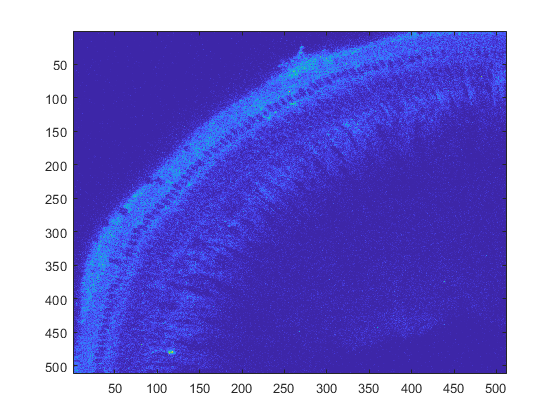

Cannot find an exact (case-sensitive) match for 'getFrame'

The closest match is: getframe in C:\Program Files\MATLAB\R2020a\toolbox\matlab\graphics\printing\getframe.m

[fp,name,ext]=fileparts(fileList{1});
name = [name '_figVideo'];

frameGrab = [];
oimg = []; index = 1;
figure; 
for i = 1:1:100 %because there are two channels in your image, only select GCaMP signal
    imagesc(imgdata{i,1});
    frameGrab(i) = getframe;
end


ext = '.mp4'
fileOutput = [fp '\' name ext];
if strcmp(ext,'.avi')
    v = VideoWriter(fileOutput,'Uncompressed AVI');
elseif strcmp(ext,'.mp4')
    v = VideoWriter(fileOutput,'MPEG-4');
    v.Quality = 100;
end
    
v.FrameRate = 10;
open(v);

for i=1:size(M,2)
    writeVideo(v,M(i).cdata);
end
close(v);

%Panel D (traces)
IHCfiles = loadFileList('.\Data\P0 MRS2500\*_IHCstructwhole*');
ISCfiles = loadFileList('.\Data\P0 MRS2500\*_ISC*');
IHC = load(IHCfiles{1})

IHC = struct with fields:
    IHCstruct: [1×1 struct]


IHCstruct = IHC.IHCstruct;

rois = IHCstruct.smoothroi;
numToShow = 75; n = size(rois,2)

n = 83

if numToShow > n
    numToShow = n;
end
temp = randperm(n)';
temp = sort(temp(1:numToShow));

figure; plotOffset(IHCstruct.smoothroi(1:1800,temp),0.5)

ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [1440 918 560 420]
       Units: 'pixels'

  Show all properties


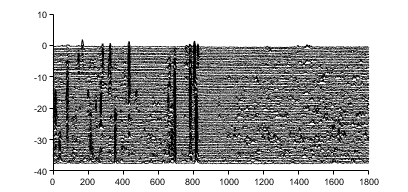

figQuality(gcf,gca,[4.25 2]);
export_fig('.\EPS Panels\PanelD_IHCs.eps');

%Panel E (ISC traces)
ISC = load(ISCfiles{5});
ISCstruct = ISC.ISCstruct;
rois = ISCstruct.rois;
numToShow = 75; n = size(rois,2)

n = 216

if numToShow > n
    numToShow = n;
end
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plotOffset(rois(1:1800,temp),0.5)

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 56
        Name: ''
       Color: [1 1 1]
    Position: [1440 918 560 420]
       Units: 'pixels'

  Show all properties


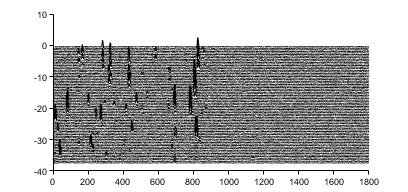

figQuality(gcf,gca,[4.25 2]);
export_fig('.\EPS Panels\PanelE_ISCs.eps');

%Quantification
IHCstructs = loadCellStructs('.\Data\P0 MRS2500\*_IHCstruct.mat');
IHCstructsMRS = loadCellStructs('.\Data\P0 MRS2500\*_IHCstructMRS2500.mat');
ISCstructs = loadCellStructs(['.\Data\P0 MRS2500\*_ISCdata.mat*']);

IHCfreq = []; IHCfreqMRS = [];
ISCfreq = []; ISCfreqMRS = [];

for i = 1:size(IHCstructs,2)
    IHCfreq(i) = size(IHCstructs(i).event,2)/5;
    IHCfreqMRS(i) = size(IHCstructsMRS(i).event,2)/5;
    IHCarea(i) = mean([IHCstructs(i).event.area]);
    if IHCfreqMRS(i) ~= 0
        [IHCstructsMRS(i).event.area]
        IHCareaMRS(i) = mean([IHCstructsMRS(i).event.area]);
    else
        IHCareaMRS(i) = 0;
    end
    IHCcorr(i) = mean(prctile(IHCstructs(i).corr,90));
    IHCcorrMRS(i) = mean(prctile(IHCstructsMRS(i).corr,90));
    
    tempISC = [ISCstructs(i).event([ISCstructs(i).event.timeStart] <= 600)];
    tempISCMRS = [ISCstructs(i).event([ISCstructs(i).event.timeStart] > 1200 & [ISCstructs(i).event.timeStart] <=1800)];
    ISCfreq(i) = size(tempISC,2)/5;
    ISCfreqMRS(i) = size(tempISCMRS,2)/5;
    ISCarea(i) = mean([tempISC.area]);
    if ISCfreqMRS(i) ~= 0
        ISCareaMRS(i) = mean([tempISCMRS.area]);
    else
        ISCareaMRS(i) = 0;
    end
end

ans = 4

ans =      6    13     4     4


ans = 4

%Panel E
h1 = compare2Px2(IHCfreq', IHCfreqMRS', ISCfreq', ISCfreqMRS',{'Baseline','MRS2500','Baseline','MRS2500'}, 'Events per minute', [1.5 2], [15 8], 'k', 'r')

    0.0041



h1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 79
        Name: ''
       Color: [1 1 1]
    Position: [1440 918 560 420]
       Units: 'pixels'

  Show all properties


xtickangle(45);
ylim([0 15]);
figQuality(gcf,gca,[1.5 2]);

h2 = compare2Px2(IHCarea', IHCareaMRS', ISCarea', ISCareaMRS',{'Baseline','MRS2500','Baseline','MRS2500'}, '# ROIs per event', [1.5 2], [15 8], 'k', 'r')

    0.0230



h2 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 80
        Name: ''
       Color: [1 1 1]
    Position: [1440 918 560 420]
       Units: 'pixels'

  Show all properties


xtickangle(45);
ylim([0 15]);
figQuality(gcf,gca,[1.5 2]);

h3 = compare2P(IHCcorr',IHCcorrMRS',{'Baseline','MRS2500'},'Correlation Coef',[3 2],[15 10],'k','r');

    0.0037



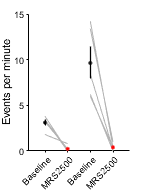

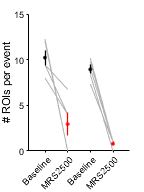

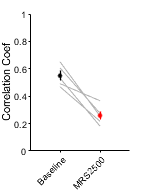

xtickangle(45);
ylim([0 1]);
figQuality(gcf,gca,[1.5 2]);

handleTheSubplot({h1,h2,h3},[1 3]);

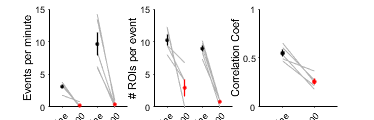

figQuality(gcf,gca,[3.9,1.25]);
export_fig('./EPS Panels/PanelE.eps')

[h,p,ci,stats] = ttest(IHCfreq,IHCfreqMRS)

h = 1

p = 0.0041

ci =     1.5244    4.2356


stats = struct with fields:
    tstat: 5.8985
       df: 4
       sd: 1.0918


[h,p2,ci2,stats2] = ttest(ISCfreq,ISCfreqMRS)

h = 1

p2 = 0.0050

ci2 =     4.6630   13.8170


stats2 = struct with fields:
    tstat: 5.6050
       df: 4
       sd: 3.6862



[h,p3,ci3,stats3] = ttest(IHCarea,IHCareaMRS)

h = 1

p3 = 0.0230

ci3 =     1.6472   12.9109


stats3 = struct with fields:
    tstat: 3.5885
       df: 4
       sd: 4.5357


[h,p4,ci4,stats4] = ttest(ISCarea,ISCareaMRS)

h = 1

p4 = 7.6631e-05

ci4 =     6.7891    9.5108


stats4 = struct with fields:
    tstat: 16.6279
       df: 4
       sd: 1.0960



[h,p5,ci5,stats5] = ttest(IHCcorr,IHCcorrMRS)

h = 1

p5 = 0.0037

ci5 =     0.1581    0.4234


stats5 = struct with fields:
    tstat: 6.0853
       df: 4
       sd: 0.1068
